# Rumor Propagation Through Random and Small World Networks

## Erdös–Rényi Network Model

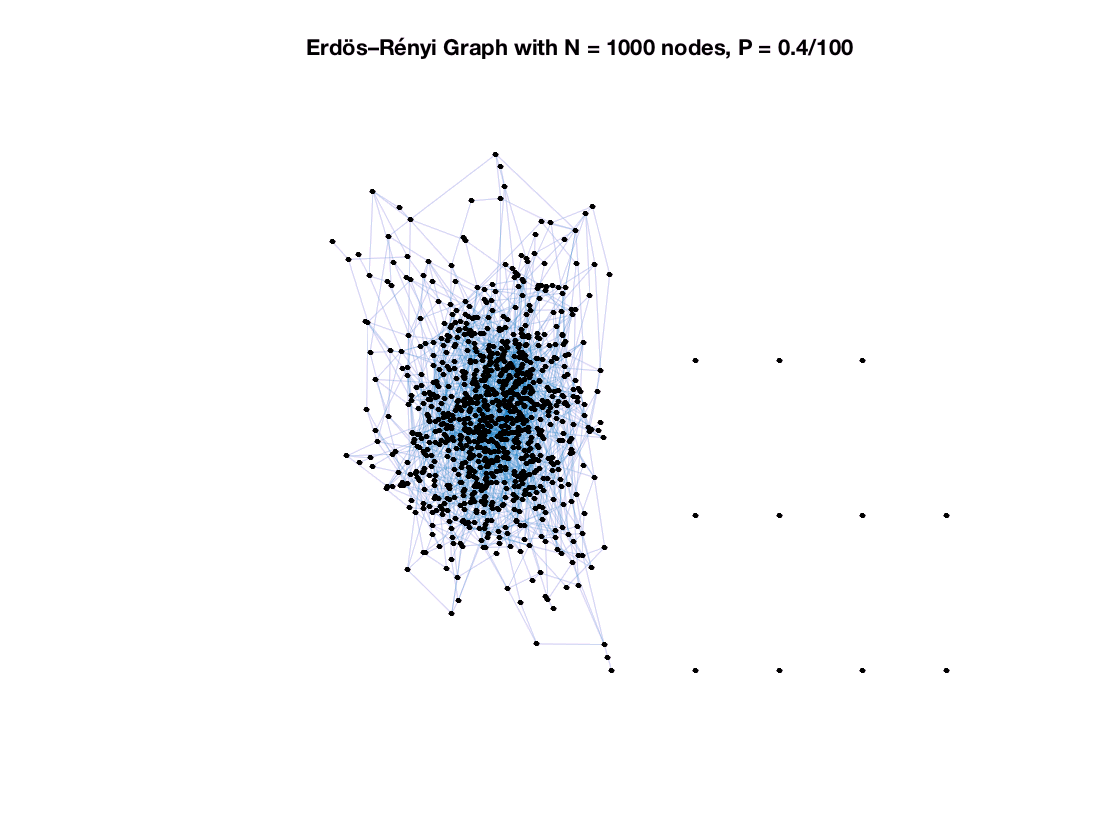

n = 1000;
p = (0.4/100);
randomMatrix= rand(n);
A = triu(randomMatrix<p,1);
A = sparse(A);
A = A+A';
G = graph(A);
plot(G,'NodeColor', 'k', 'EdgeAlpha', 0.2)
axis off
title('Erdös–Rényi Graph with N = 1000 nodes, P = 0.4/100')

## Degree Centrality, Erdös–Rényi Random Graph

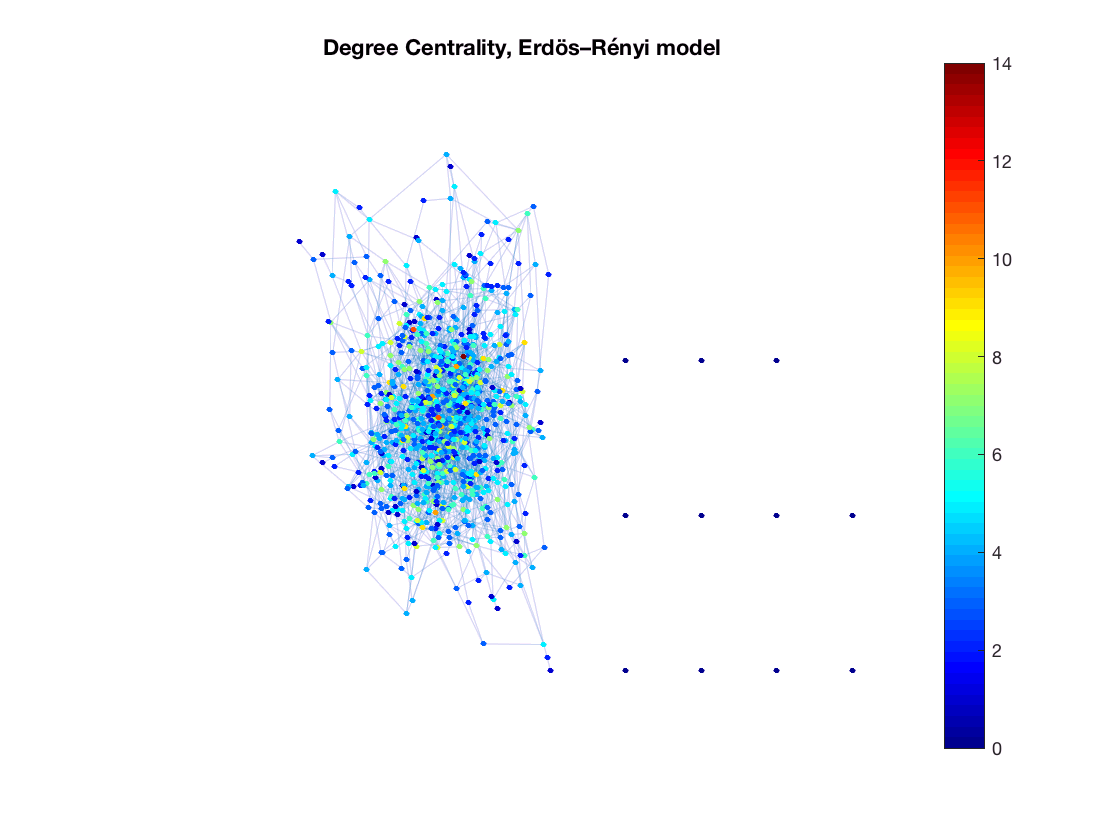

h = plot(G,'NodeColor', 'r', 'EdgeAlpha', 0.2);
degree = centrality(G, 'degree');
h.NodeCData = degree;
axis off
colormap jet
colorbar
title('Degree Centrality, Erdös–Rényi model')


S = sum(degree);
avgDeg = S/n

avgDeg = 4.1540

NN = numedges(G)

NN = 2077

## Closeness Centrality, Erdös–Rényi Random Graph

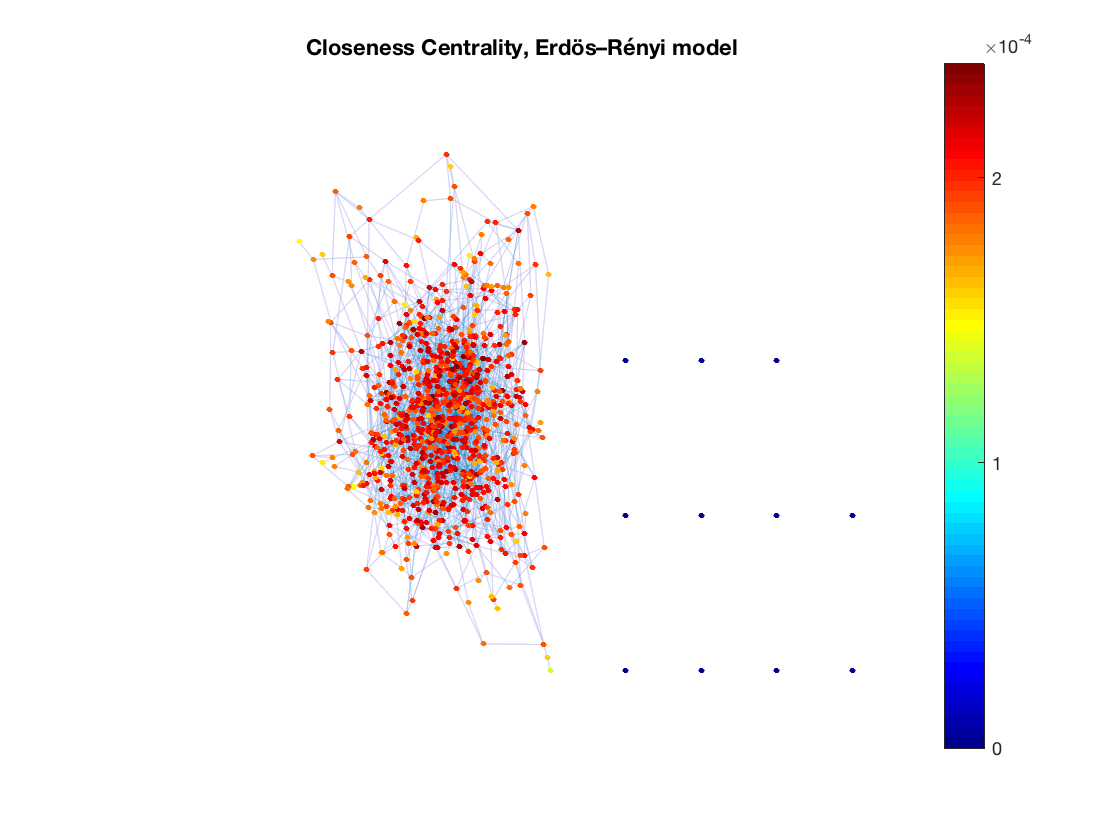

h = plot(G,'NodeColor', 'k', 'EdgeAlpha', 0.2);
closeness = centrality(G,'closeness');
h.NodeCData = closeness;
colormap jet
colorbar
axis off
title('Closeness Centrality, Erdös–Rényi model')


S = sum(closeness);
avgClose = S/n

avgClose = 1.9752e-04

## Betweenness Centrality, Erdös–Rényi Random Graph

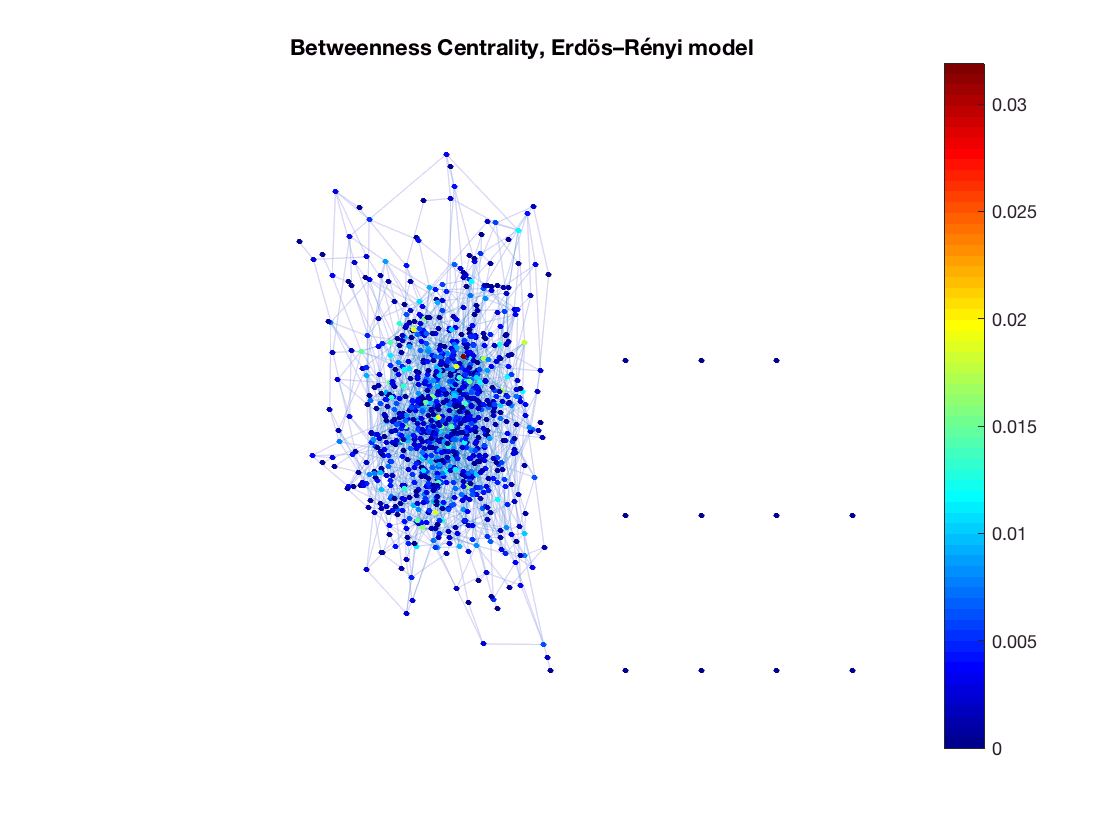

h = plot(G,'NodeColor', 'k', 'EdgeAlpha', 0.2);
G.Nodes.betweenness = zeros(n,1);
BC = centrality(G,'betweenness');
h.NodeCData = (2*BC)./((n-2)*(n-1));
colormap(jet)
colorbar
axis off
title('Betweenness Centrality, Erdös–Rényi model')


S = sum((2*BC)./((n-2)*(n-1)));
avgBtwn = S/n

avgBtwn = 0.0039

## Eigenvector Centrality, Erdös–Rényi Random Graph

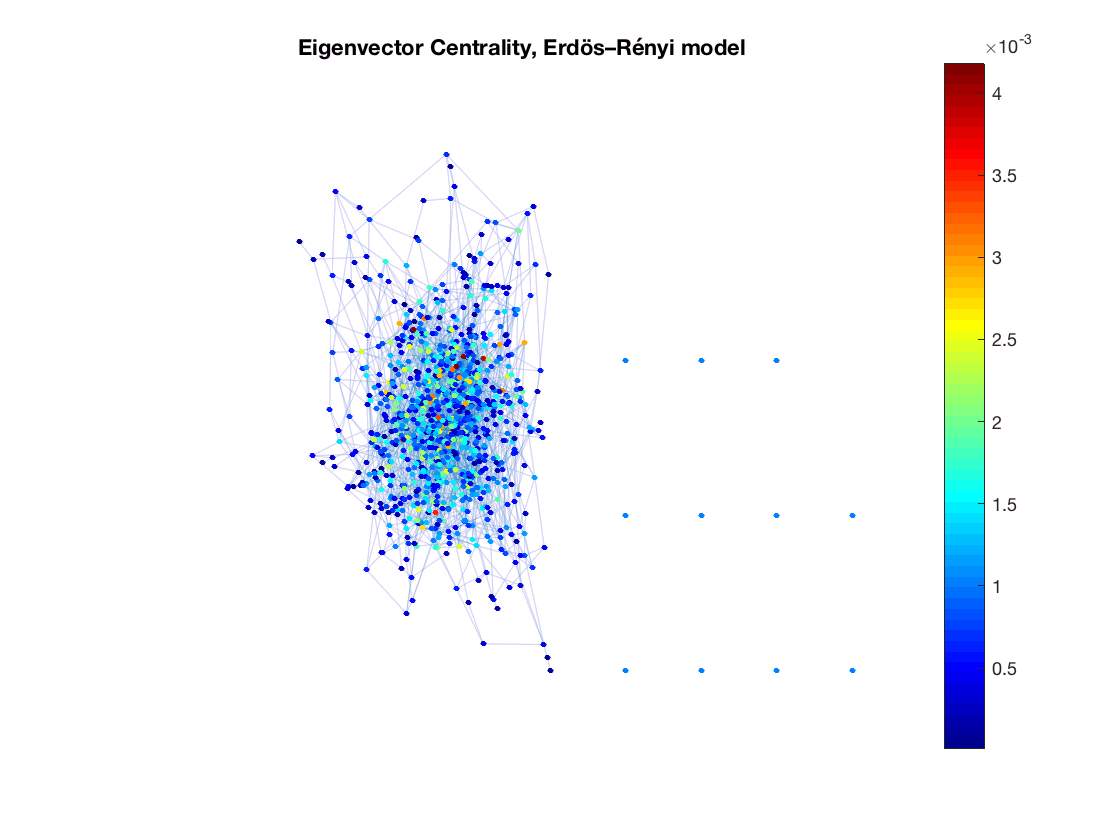

h = plot(G, 'NodeColor', 'k', 'EdgeAlpha', 0.2);
eig = centrality(G,'eigenvector');
h.NodeCData = eig;
colormap jet
colorbar
axis off
title ('Eigenvector Centrality, Erdös–Rényi model')


S = sum(eig);
avgEig = S/n

avgEig = 1.0000e-03

## Basic Propagation Model, Erdös–Rényi Random Graph

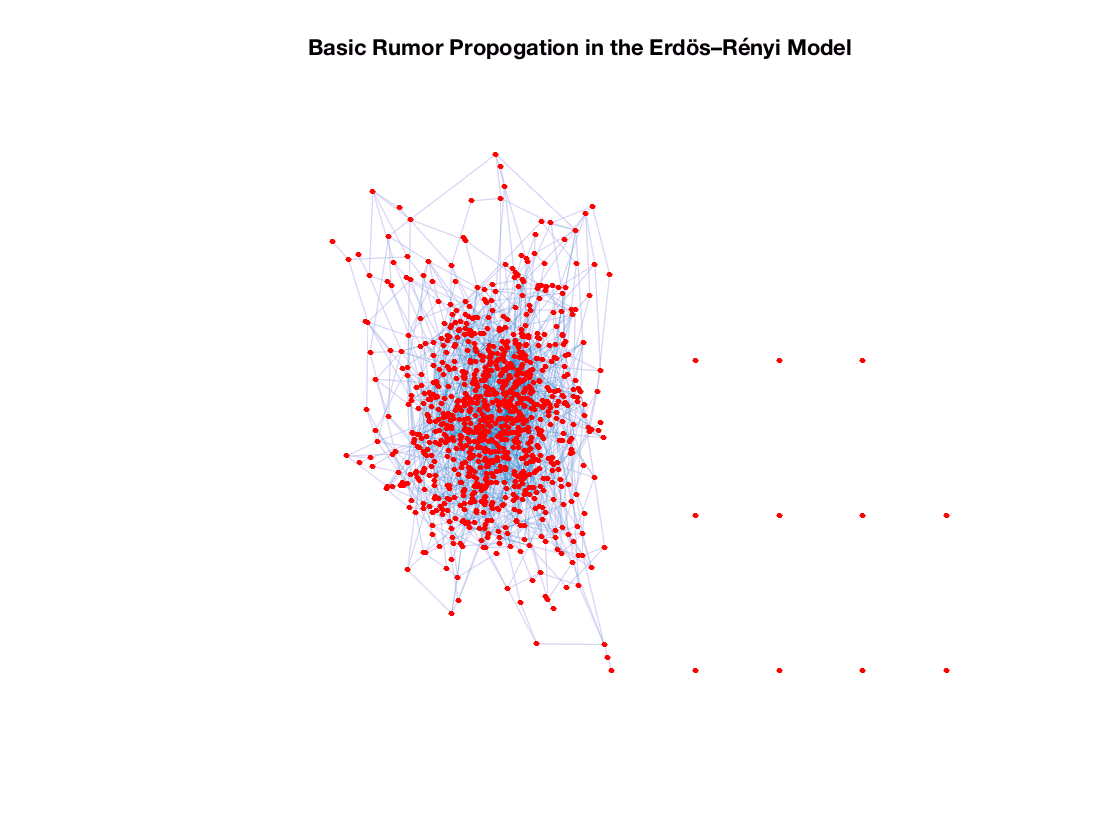

BasicERTrial = 1;
r = randi([1,n]);
G.Nodes.status = zeros(n,1);
G.Nodes.status(r,1) = 1;
array = find(G.Nodes.status);

c = 1;
t = 1;   

h = plot(G,'NodeColor', 'k', 'EdgeAlpha', 0.2);
highlight(h, array, 'NodeColor', 'r');
axis off
BasicER(c) = getframe;            
c = c+1;

for i = 1:n
    if isempty(neighbors(G, i)) == 1
        G.Nodes.status(i) = 1;        
    end
end


while size(find(G.Nodes.status)) ~=n
    for k = 1:size(array)
        if G.Nodes.status(array(k,1),1) == 1
            N = neighbors(G, array(k,1));
            if (N ~= 0)
                P = rand(size(N,1),1);
                for v = 1:size(N)              
                    if (G.Nodes.status(N(v,1),1) == 1)
                        continue                     
                    else
                        if t > P(v,1)                            
                            G.Nodes.status(N(v,1),1) = 1;
                            newarray = find(G.Nodes.status);
                        end                                                 
                    end
                end
            end
        end        
    end
    array = newarray;
    BasicERTrial = BasicERTrial + 1;
    
    highlight(h, array, 'NodeColor', 'r');
    drawnow
    axis off
    BasicER(c) = getframe;            
    c = c+1;
end    
axis off
title('Basic Rumor Propogation in the Erdös–Rényi Model')

## Maki-Thompson Propagation Model, Erdös–Rényi Random Graph

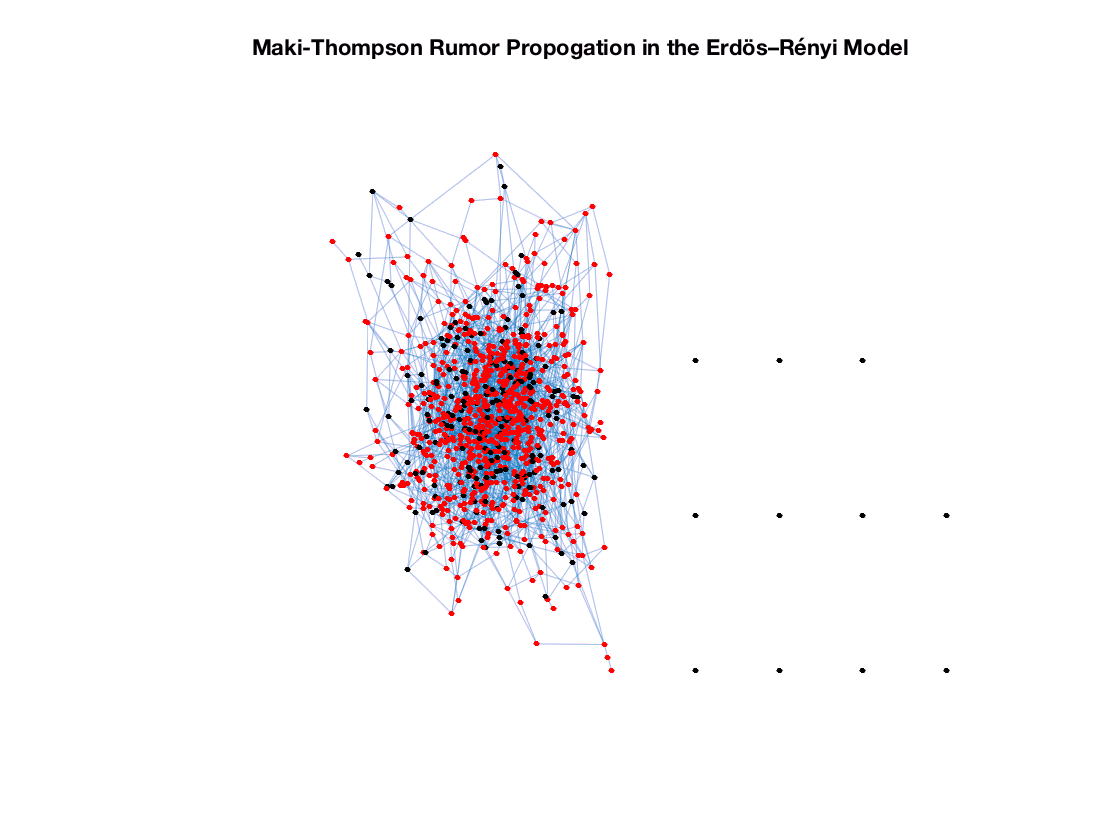

MakiERTrial = 0;
r = randi([1,n]);
G.Nodes.role = zeros(n,1);
G.Nodes.status = zeros(n,1);
G.Nodes.status(r,1) = 1;
array = find(G.Nodes.status);
b = 0.8;                        % probability of being spreader
t = 1;
c = 1;

for x = 1:n
    p = rand;
    if p < b                    % if random prob < chosen prob, designate node as spreader
        G.Nodes.role(x,1) = 1; 
    end
end

h = plot(G,'NodeColor', 'k', 'EdgeAlpha', 0.35);
highlight(h, array, 'NodeColor', 'r');   
axis off;
MakiER(c) = getframe;
c = c+1;
trial = 0;

count = 1;
while count ~= 0
    trial = trial +1;
    count = 0;
    for k = 1:size(array)        
        N = neighbors(G,array(k,1));
        if N~=0                
            P = rand(size(N,1),1);
            for v = 1:size(N) 
                if (G.Nodes.status(N(v,1),1) == 1)
                    continue                    
                else
                    if t > P(v,1)
                        if G.Nodes.role(N(v,1),1) == 1
                            G.Nodes.status(N(v,1),1) = 1;
                            newarray = find(G.Nodes.status);                              
                        end
                    end
                end
            end
        end
    end
    array = newarray;
    MakiERTrial = MakiERTrial + 1;
    
    highlight(h, array, 'NodeColor', 'r');
    drawnow
    axis off
    MakiER(c) = getframe;
    c = c+1;
    
    for i = 1:size(array)
        X = neighbors(G,array(i,1));
            for v = 1:size(X)
                if (G.Nodes.role(X(v,1),1) == 1) && (G.Nodes.status(X(v,1),1)  == 0)   
                    count = count + 1;
                    break;
                end
                if count~= 0
                    break;
            end
        end
    end
    
end
axis off
title('Maki-Thompson Rumor Propogation in the Erdös–Rényi Model')

## Watts-Strogatz Network Model

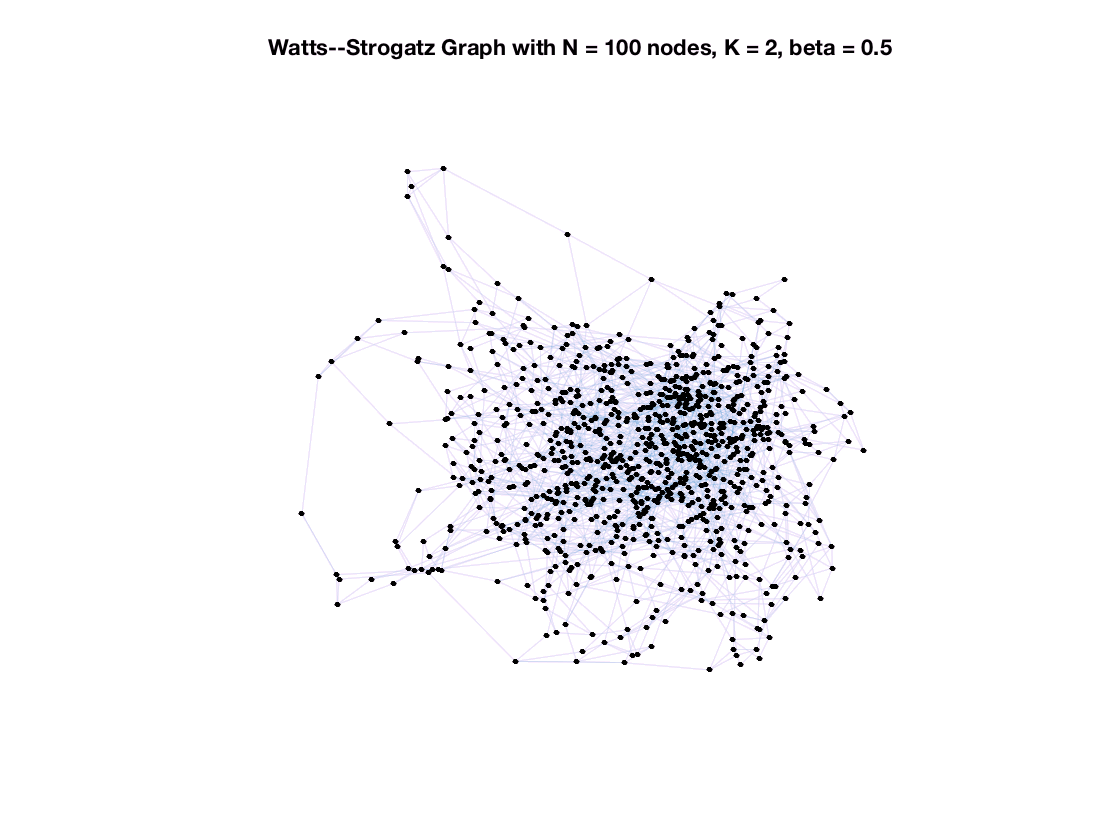

k = 2;
beta = 0.3;
s = repelem((1:n)',1,k);
t = s + repmat(1:k,n,1);
t = mod(t-1,n)+1;
for source=1:n    
    switchEdge = rand(k, 1) < beta;
   
    newTargets = rand(n, 1);
    newTargets(source) = 0;
    newTargets(s(t==source)) = 0;
    newTargets(t(source, ~switchEdge)) = 0;
    
    [~, ind] = sort(newTargets, 'descend');
    t(source, switchEdge) = ind(1:nnz(switchEdge));
end

H = graph(s,t);
plot(H,'NodeColor', 'k', 'EdgeAlpha', 0.1)
axis off
title('Watts--Strogatz Graph with N = 100 nodes, K = 2, beta = 0.5')

## Degree Centrality, Watts-Strogatz Small-World Graph

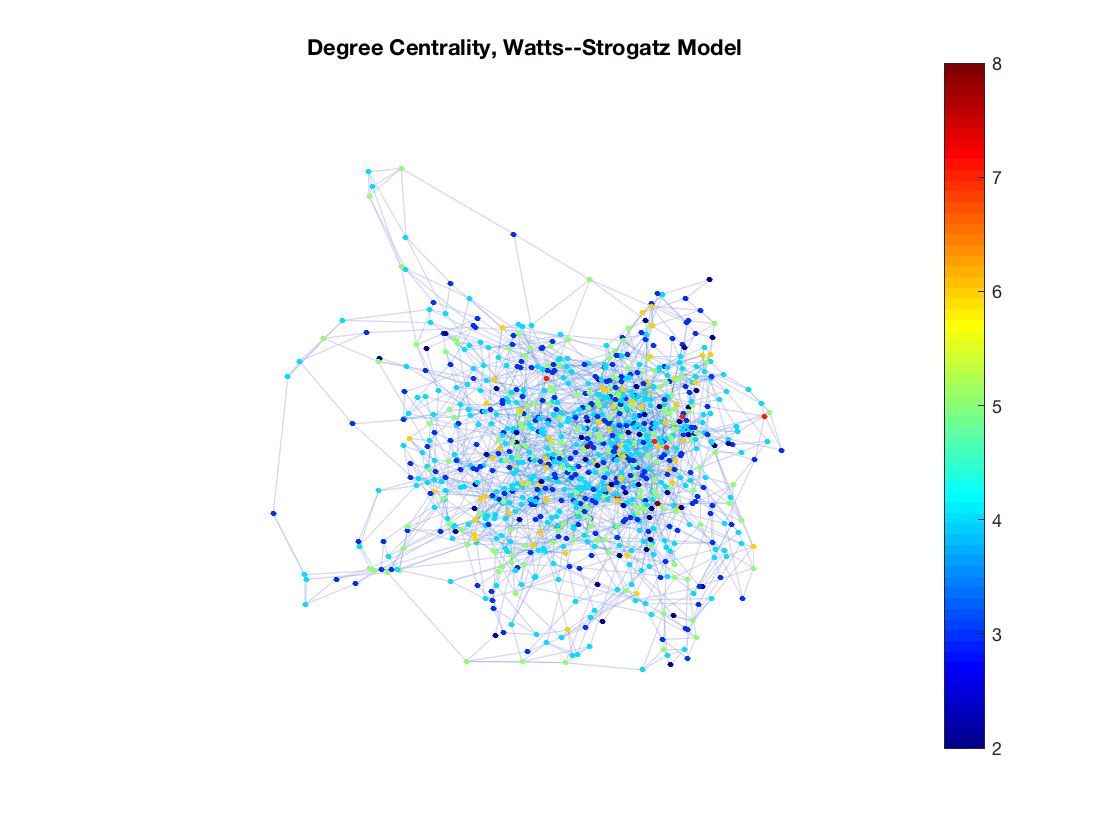

h = plot(H,'NodeColor', 'k', 'EdgeAlpha', 0.2);
degree = centrality(H, 'degree');
h.NodeCData = degree;
colormap jet
colorbar
axis off
title('Degree Centrality, Watts--Strogatz Model')


S = sum(degree);
avgDeg2 = S/n

avgDeg2 = 4


HH = numedges(H)

HH = 2000

## Closeness Centrality, Watts-Strogatz Small-World Graph

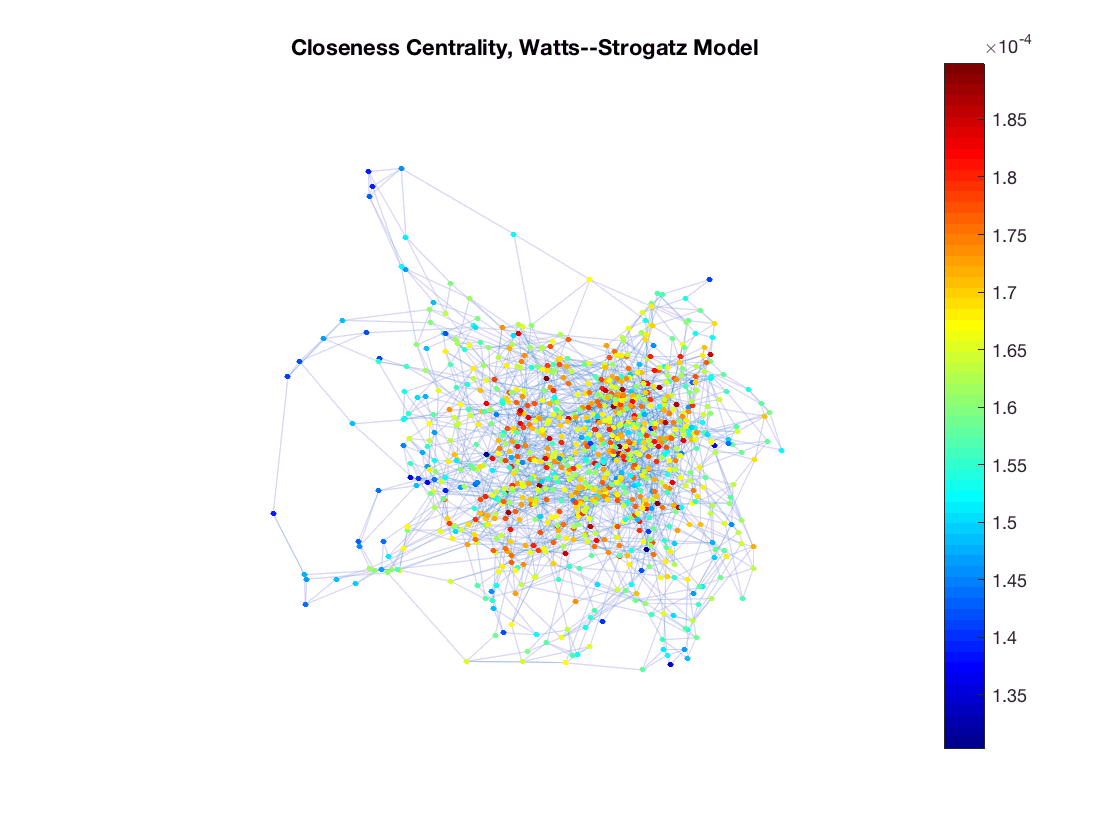

h = plot(H,'NodeColor', 'k', 'EdgeAlpha', 0.2);
closeness = centrality(H,'closeness');
h.NodeCData = closeness;
colormap jet
colorbar
axis off
title('Closeness Centrality, Watts--Strogatz Model')


S = sum(closeness);
avgClose2 = S/n

avgClose2 = 1.6450e-04

## Eigenvector Centrality, Watts- Strogatz Small-World Graph

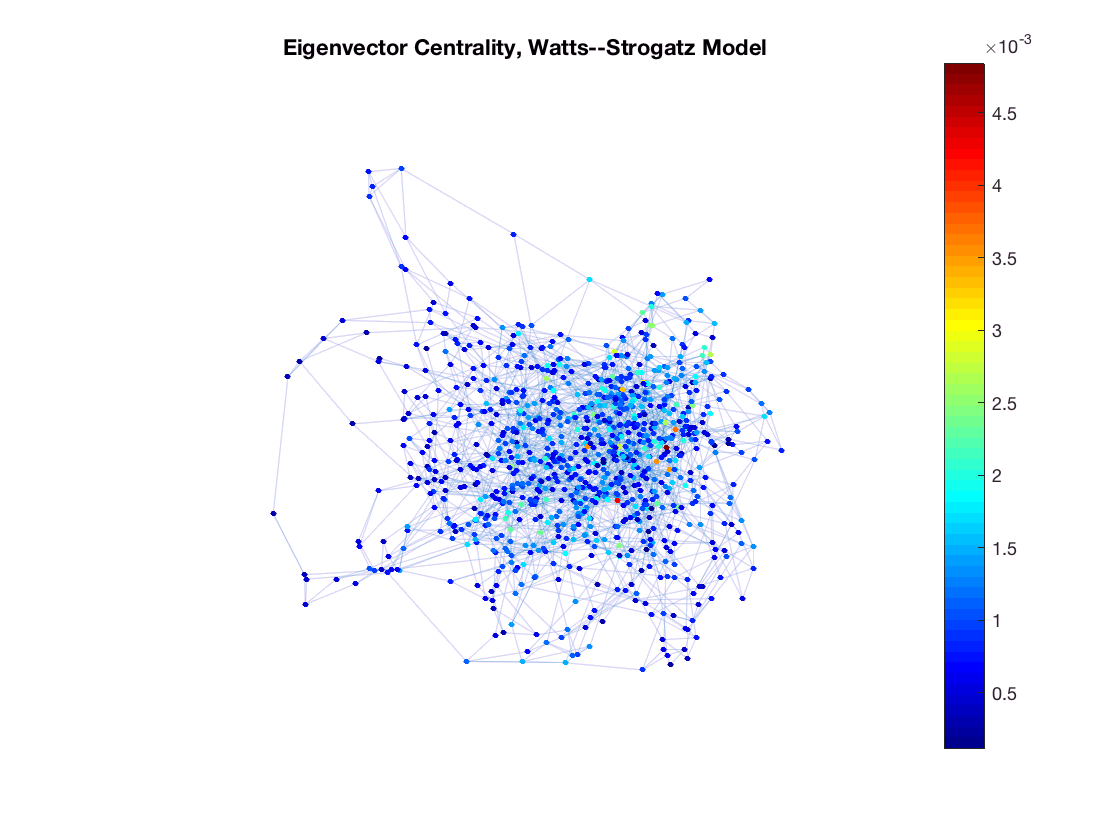

h = plot(H, 'NodeColor', 'k', 'EdgeAlpha', 0.2);
eig2 = centrality(H,'eigenvector');
h.NodeCData = eig2;
colormap jet
colorbar
axis off
title ('Eigenvector Centrality, Watts--Strogatz Model')


S = sum(eig2);
avgEig2 = S/n

avgEig2 = 1.0000e-03

## Betweenness Centrality, Watts-Strogatz Small-World Graph

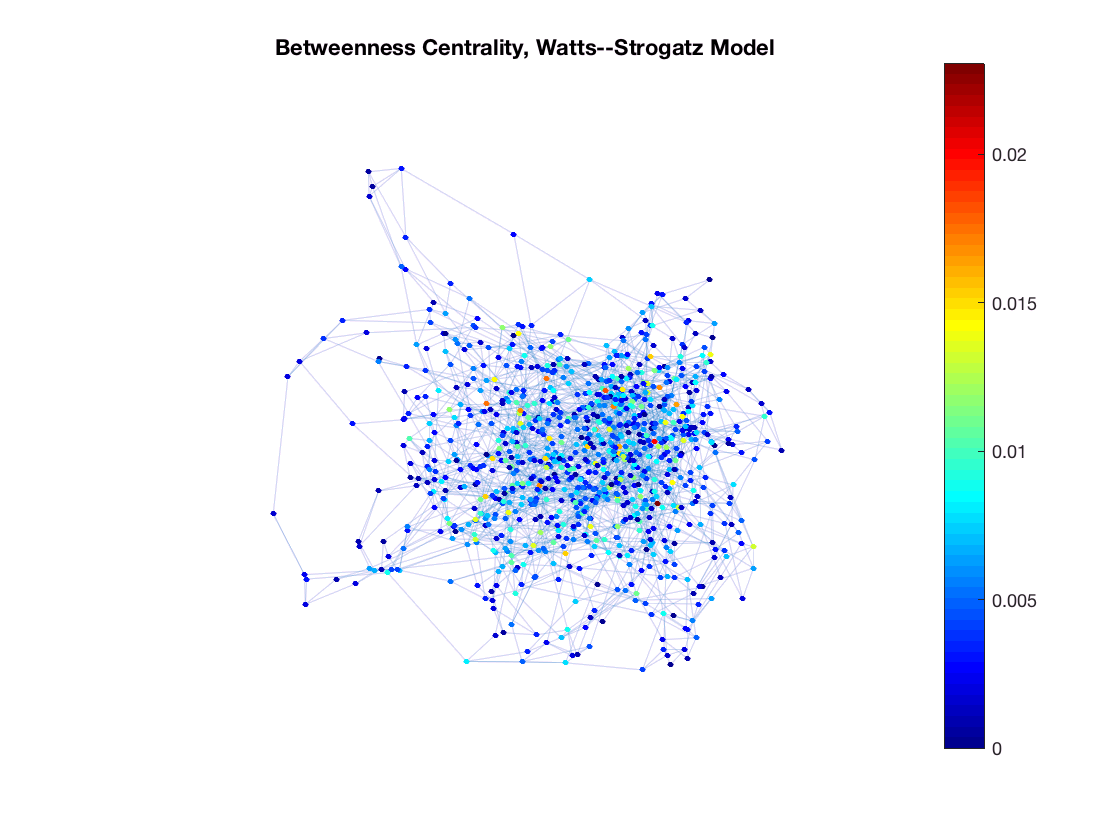

h = plot(H,'NodeColor', 'k', 'EdgeAlpha', 0.2);
BC = centrality(H,'betweenness');
h.NodeCData = (2*BC)./((n-2)*(n-1));
colormap(jet)
colorbar
axis off
title('Betweenness Centrality, Watts--Strogatz Model')


S = sum((2*BC)./((n-2)*(n-1)));
avgBtwn2 = S/n

avgBtwn2 = 0.0051

## Hubs Watts-Strogatz Model

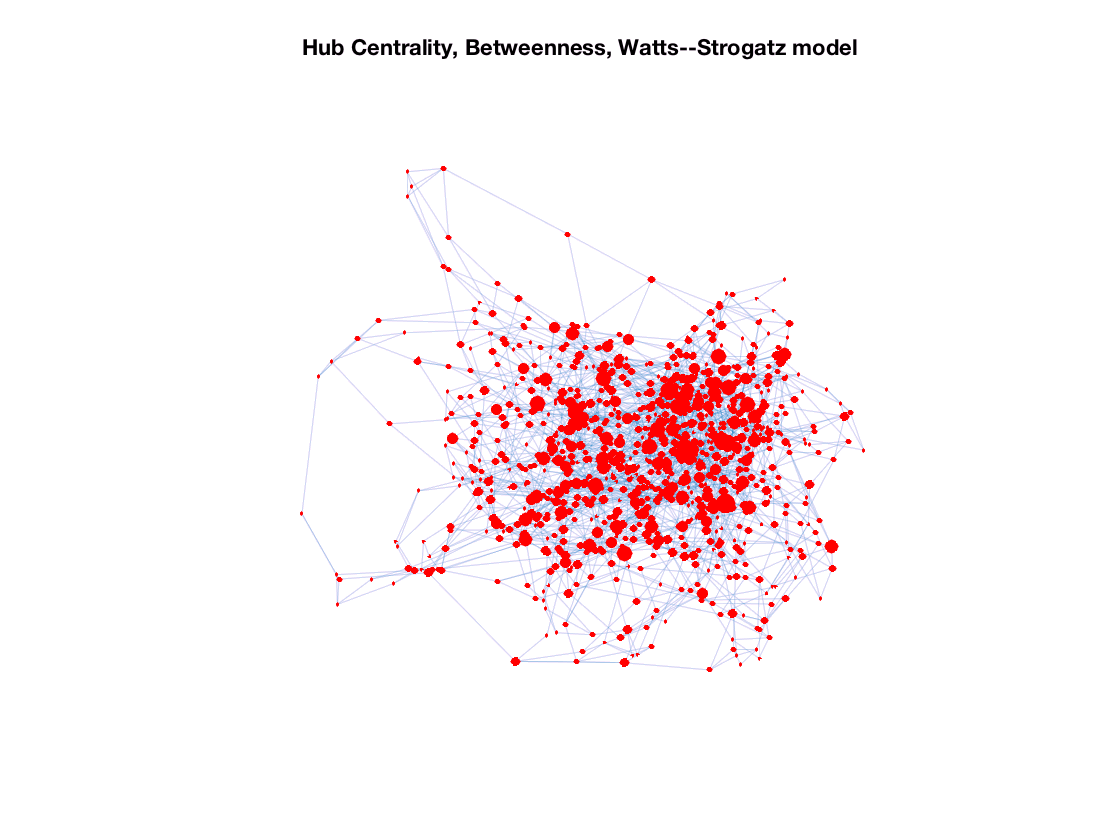


H.Nodes.role = ones(n,1);
[~,sortIndex] = sort(closeness(:),'descend');                                                   
maxCloseIndex = sortIndex(1:220);
[~,sortIndex] = sort(BC(:),'descend');                                                   
maxBCIndex = sortIndex(1:220);
[~,sortIndex] = sort(eig2(:),'descend');                                                   
maxEigIndex = sortIndex(1:220);
choice = 3; %Nodes w/ large (1)closeness/(2)betweenness/(3)eigenvalue measures designated as stiflers
if choice == 1
    for i = 1:220
        H.Nodes.role(maxCloseIndex(i)) = 0;
    end
elseif choice == 2
    for i = 1:220
        H.Nodes.role(maxBCIndex(i)) = 0;
    end
elseif choice == 3
    for i = 1:220
        H.Nodes.role(maxEigIndex(i)) = 0;
    end   
end


h = plot(H, 'NodeColor', 'r', 'EdgeAlpha', 0.2);
edges = linspace(min(BC),max(BC), 10);
bins = discretize(BC,edges);
h.MarkerSize = bins;

axis off
title ('Hub Centrality, Betweenness, Watts--Strogatz model')

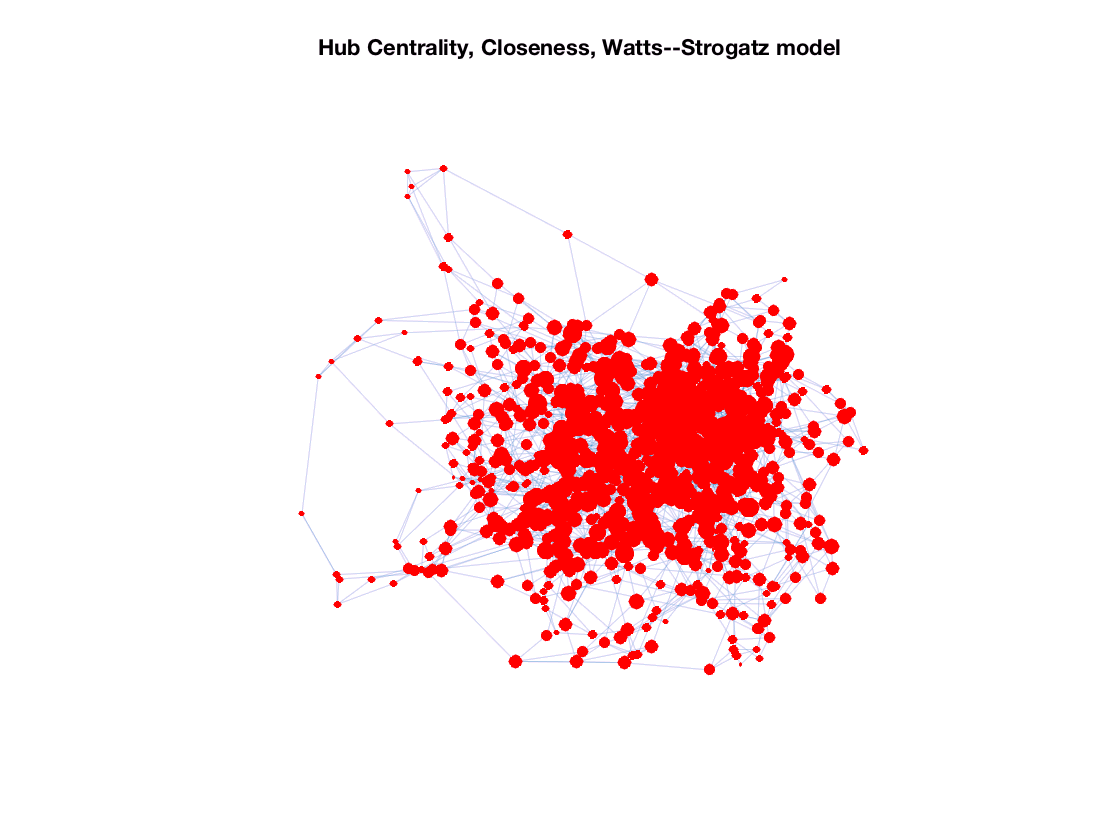


h = plot(H, 'NodeColor', 'r', 'EdgeAlpha', 0.2);
edges = linspace(min(closeness),max(closeness), 10);
bins = discretize(closeness,edges);
h.MarkerSize = bins;

axis off
title ('Hub Centrality, Closeness, Watts--Strogatz model')

## Basic Propogation Model, Watts-Strogatz Small-World Graph

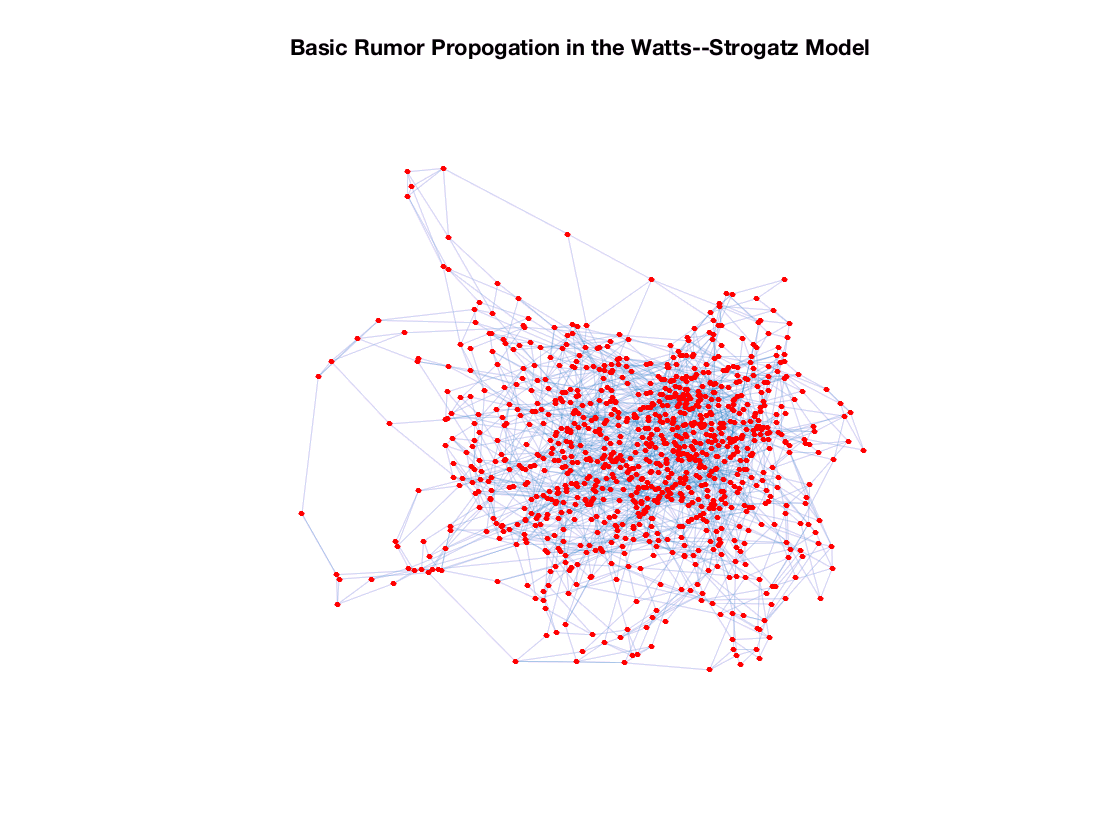

H.Nodes.status = zeros(n,1);
BasicWSTrial = 0;
r = randi([1,n]);
H.Nodes.status(r,1) = 1;      
array = find(H.Nodes.status);
t = 1;
c = 1;

h = plot(H,'NodeColor', 'k', 'EdgeAlpha', 0.2);
highlight(h, array, 'NodeColor', 'r');
axis off
BasicWS(c) = getframe;            
c = c+1;

while size(find(H.Nodes.status),1) ~= n
    for k = 1:size(array)
        if H.Nodes.status(array(k,1),1) == 1
            N = neighbors(H, array(k,1));
            if (N ~= 0)
                P = rand(size(N,1),1);
                for v = 1:size(N)              
                    if (H.Nodes.status(N(v,1),1) == 1)
                        continue                     
                    else
                        if t > P(v,1)                            
                            H.Nodes.status(N(v,1),1) = 1;
                            newarray = find(H.Nodes.status);
                        end                      
                    end
                end
            end
        end        
    end
    array = newarray;
    BasicWSTrial = BasicWSTrial + 1;
    
    highlight(h, array, 'NodeColor', 'r');
    drawnow
    axis off
    BasicWS(c) = getframe;            
    c = c+1;
end    

axis off
title('Basic Rumor Propogation in the Watts--Strogatz Model')

## Maki-Thompson Propagation Model, Watts-Strogatz Graph

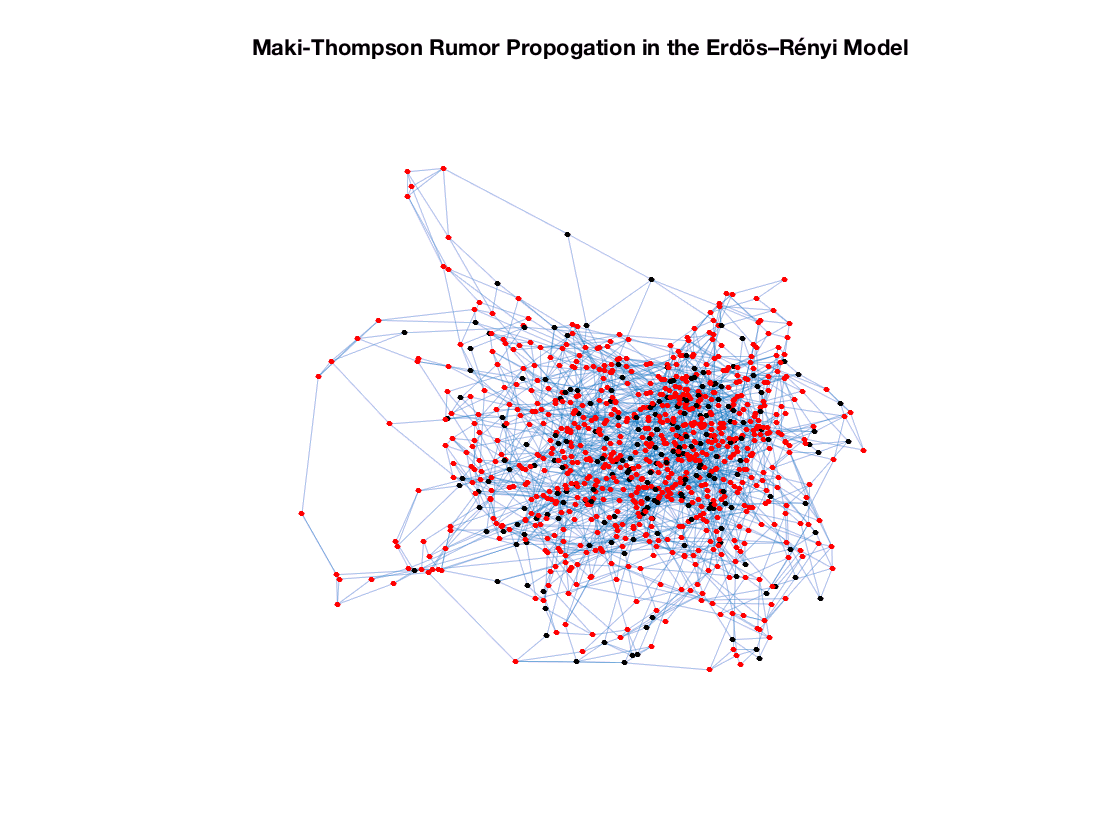

r = randi([1,n]);
MakiWSTrial = 0;
t = 1;
H.Nodes.role = zeros(n,1);
H.Nodes.status = zeros(n,1);
H.Nodes.status(r,1) = 1;
array = find(H.Nodes.status);
b = 0.8;                        % probability of being spreader
c = 1;

h = plot(H,'NodeColor', 'k', 'EdgeAlpha', 0.35);
highlight(h, array, 'NodeColor', 'r') ;   
axis off;
MakiWS(c) = getframe;
c = c+1;

% Random designation of stiflers
for x = 1:n
    p = rand;
    if p < b                   
        H.Nodes.role(x,1) = 1;
    end
end

count = 1;
while count~=0
    count = 0;
    for k = 1:size(array)
        if H.Nodes.status(array(k,1),1) == 1
            N = neighbors(H,array(k,1));
            if N~=0                
                P = rand(size(N,1),1);
                for v = 1:size(N) 
                    if (H.Nodes.status(N(v,1),1) == 1)
                        continue                    
                    else
                        if t > P(v,1)
                            if H.Nodes.role(N(v,1),1) ==1
                                H.Nodes.status(N(v,1),1) = 1;
                                newarray = find(H.Nodes.status);
                            end
                        end                       
                    end
                end
            end
        end
    end
    array = newarray;
    MakiWSTrial = MakiWSTrial + 1;
        
    highlight(h, array, 'NodeColor', 'r') ;   
    drawnow
    MakiWS(c) = getframe;
    c = c+1;

    for i = 1:size(array)
        X = neighbors(H,array(i,1));
        for v = 1:size(X)
            if ((H.Nodes.role(X(v,1),1) == 1) && (H.Nodes.status(X(v,1),1)  == 0))
                count = count + 1;
                break;
            end
        end
        if count ~= 0
            break
        end
    end

end
axis off
title('Maki-Thompson Rumor Propogation in the Erdös–Rényi Model')